# **UNIVERSITAT DE BARCELONA**

# **COMPUTER VISION **

# **LAB 11 REPORT**

**JORGE ALEXANDER & EMER RODRIGUEZ FORMISANO**

**Ensure that you have the caltech data set in a folder called data in the same directory as this script. **

**Also, ensure that you have VLFeat on your system, and set the directory below**

**VLFeat configuration:**

clear all;
VLFEAT_DIR = 'VLFEATROOT';
run(fullfile(VLFEAT_DIR,'/toolbox/vl_setup'));
vl_version;

0.9.20


**a) **

**First, train the model with a subset of categories and load it:**

Training model for class tick
Training model for class laptop
Training model for class Faces
Training model for class pizza
Training model for class accordion
Training model for class Leopards


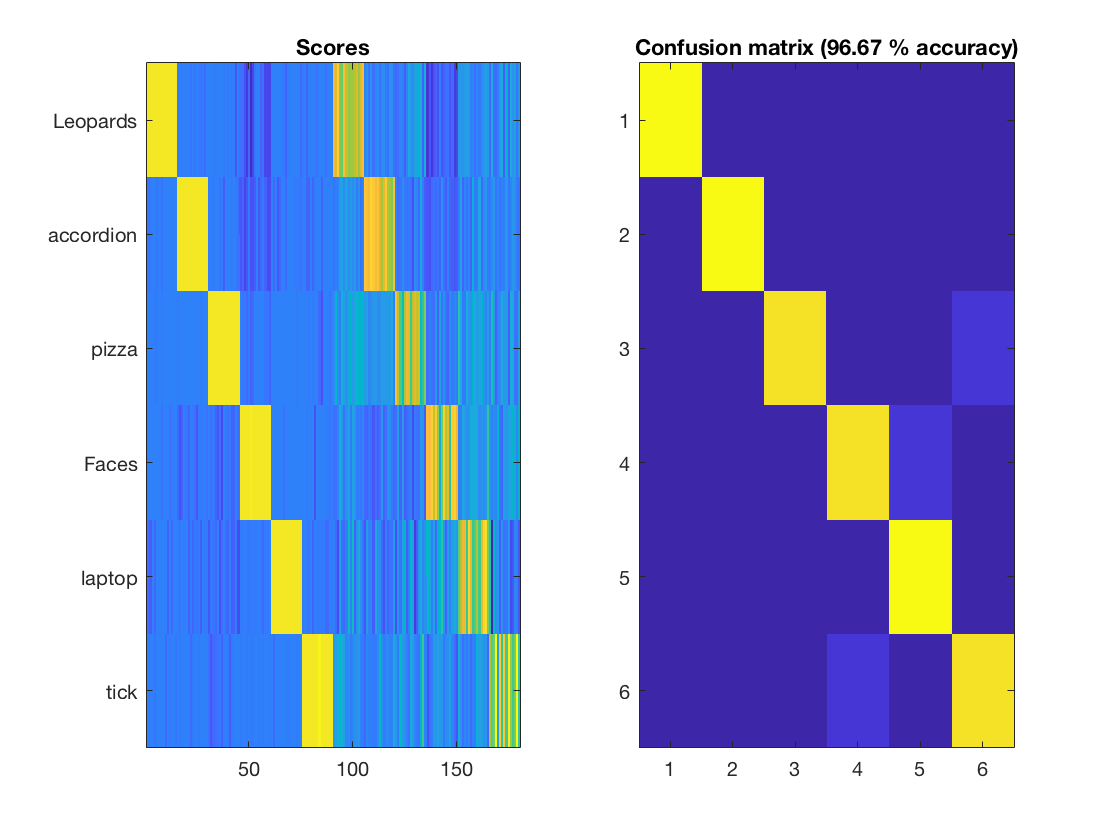

categorySubset = { 'Leopards', 'accordion', 'pizza', 'Faces', 'laptop', 'tick'};
modified_phow_caltech101(categorySubset);

modelPath = fullfile('data','baseline-model.mat');
load(modelPath);

Add a function to train visualize the images in a green framework if the classification is correct and in a red framework if it does not:

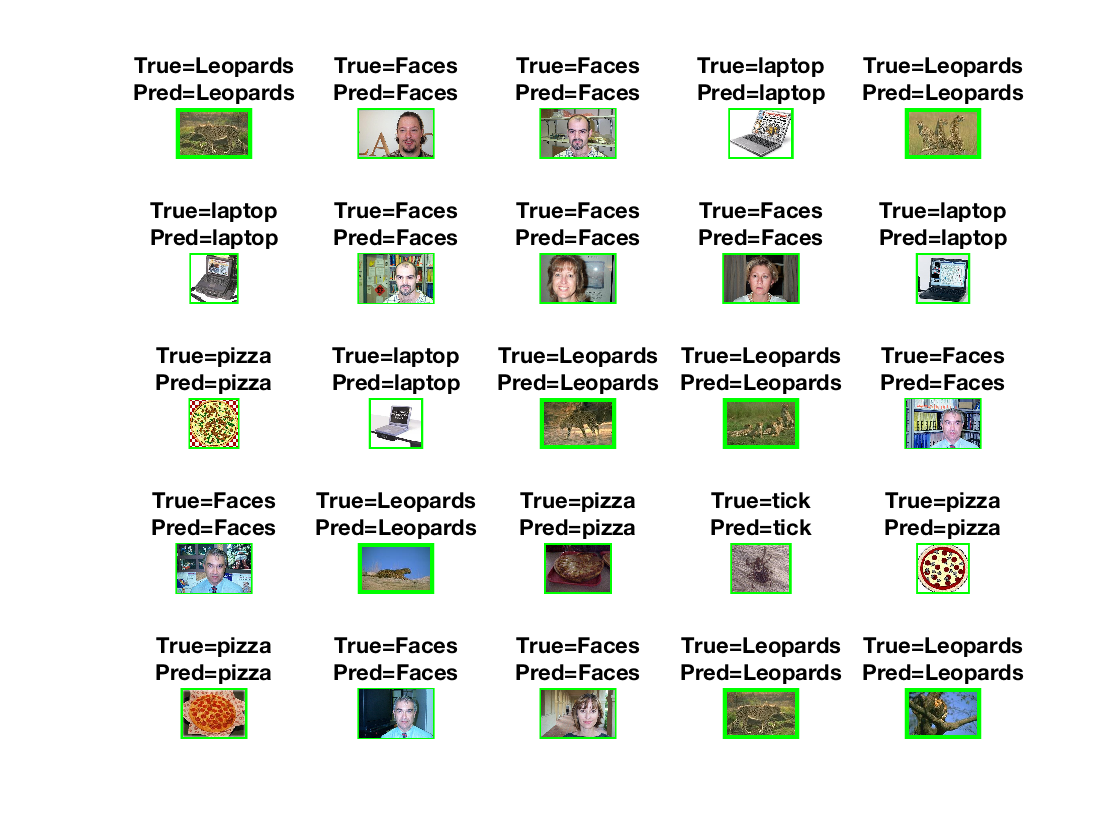

% 
% Choose imageCount random images to classify and draw border around
% 
imageCount = 25;
imageBaseDir = fullfile('data','caltech-101','101_ObjectCategories');
imagePaths = buildImagePaths(imageBaseDir, categorySubset, imageCount);
visualizeImgClass(imagePaths, model);

**b) **

***What are the PHOW descriptors?  ***

They represent the Pyramid Histogram Of visual Words. 

The function to obtain them is 

%[FRAMES, DESCRS] = vl_phow(IMG)

DESCRS, Each column of DESCRS is the descriptor of the corresponding frame in FRAMES. A descriptor is a 128-dimensional vector of class UINT8.

It represents a 4x4 spatial histogram of gradient orientations, each with 8 different directions, leading to a 4x4x8=128 dimensional vector.

FRAMES(1:2,:) are the x,y coordinates of the center of each descriptor, FRAMES(3,:) is the contrast of the descriptor, as returned by VL_DSIFT() (for colour variant, contranst is computed on the intensity channel). FRAMES(4,:) is the size of the bin of the descriptor.

***What does the Sizes parameter mean? ***

It's the scales at which the dense SIFT features are extracted. Each value is used as the spatial bin size in pixels when extracting a dense set of SIFT features from the image.

*What does happen if the Sizes parameter is augmented? *

From the lectures, the code to calculate the phow descriptors:

% step = 5;
% for size=[5,7,10,12]
%     [x,y]=meshgrid(1:step:width, 1:step:height);
%     frames = [x(:)'; y(:)'];
%     frames(3,:) = size/3;
%     frames(4,:) = 0;
%     [frames, descrs] = vl_sift(im, 'Frames', frames);
% end

It can be observed that if the size is increased the size of the bin of the descriptor is increased.				

*What does the Step parameter mean?* 

Step (in pixels) of the grid at which the dense SIFT features are extracted. This is the distance between the PHOW circles.

*What does happen if the Step parameter is augmented?*

If the step is too big, less overlapping circles will occur when extracting the SIFT features, meaning that there is a chance of missing features. If it is too small, too many overlapping circles will lead to performance impact and noisy features.

**c) **

***What are the words in the algorithm?*** 

***How are they extracted?*** 

***What is their dimension?*** 

***How their number does affect the accuracy of the results? ***

vocabPath = fullfile('data','baseline-vocab.mat'); load(vocabPath); vocab

vocab = 128×600 single matrix
         0   62.1761   10.1183   14.7342   17.2441    2.5616    6.6848   17.7059   13.8952   14.9113   10.6891    7.8350   21.3596   24.2941  112.9375    8.2162   58.0807    7.6709    3.7909    7.3984   20.2830   23.3351   11.8299    5.5197   59.2651   67.1091   10.8526   15.7973   10.0485   10.0253    8.7778   10.7255   23.7059    6.2000    8.6987    7.8118   16.9389   18.8929   15.1039    3.3415    7.9605   12.8664    5.0370   14.7042   20.5740    7.6182    4.4020   16.6894    1.7667   10.0450
         0   15.1479   19.9462    9.0127    6.3146    4.2603    3.7772   13.5163   17.3306   20.6613    0.8348    6.7184   22.7360   25.1123   36.0375    8.2342    7.1863    8.8671    1.4829   10.8618    6.2075   23.9791    8.8707    1.5669   26.7108   34.2727    4.6105   19.4932    9.8058    8.5556   40.4519    7.6863   24.7778   21.3333    6.5449   11.3529   23.7710   17.6786   19.5801    4.6937    3.8092    4.3733   15.2148   60.4859   18.4793   27.5818    6.661

We observe that the vocab consists of 128x600. The 128 represents the 128 dimensions of the sift descriptors generated by *vl_phow*, as explained before. The 600 columns represent one word each. To extract the vocab, k-means is applied to the sift descriptors. Each word of the vocab represents the centre of the k-means clusters found. Observe the classification of 16 Pizzas images below:

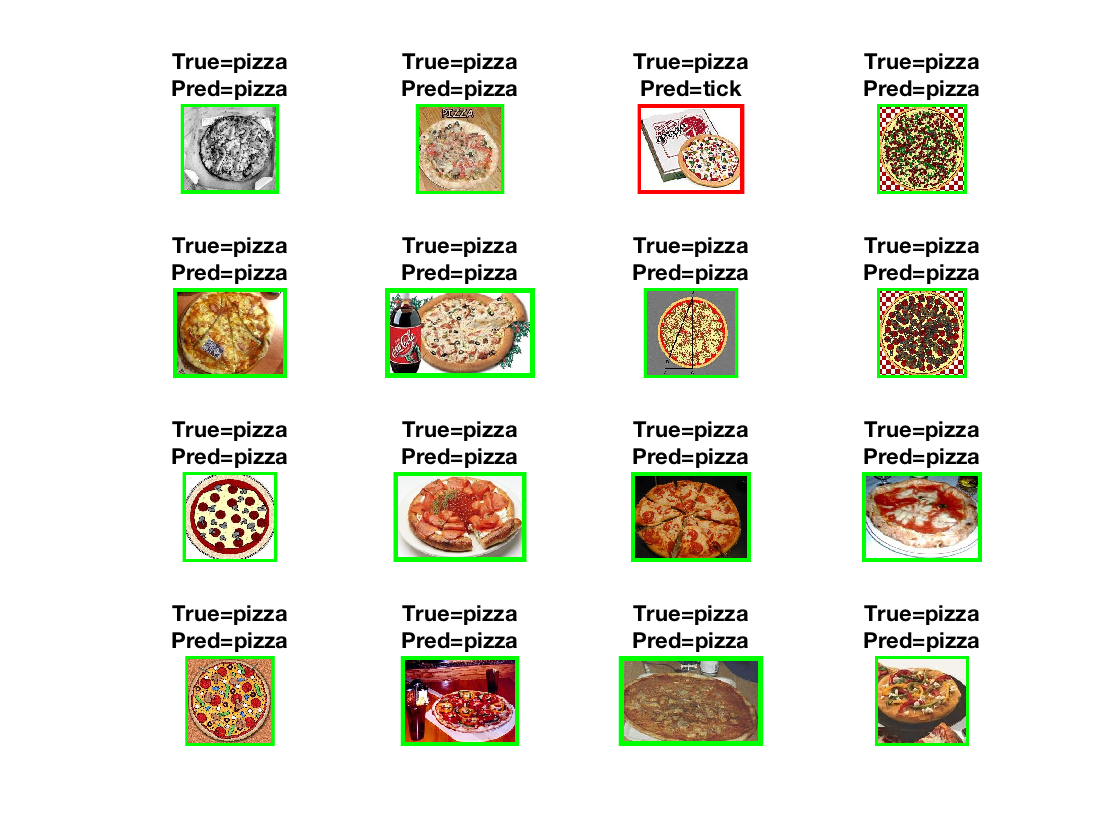

imageCount = 16; 
imagePaths = buildImagePaths(imageBaseDir, {'pizza'}, imageCount); 
visualizeImgClass(imagePaths, model);

Now we attempt to classify the same pizzas with a reduced number of words.

Training model for class tick
Training model for class laptop
Training model for class Faces
Training model for class pizza
Training model for class accordion
Training model for class Leopards


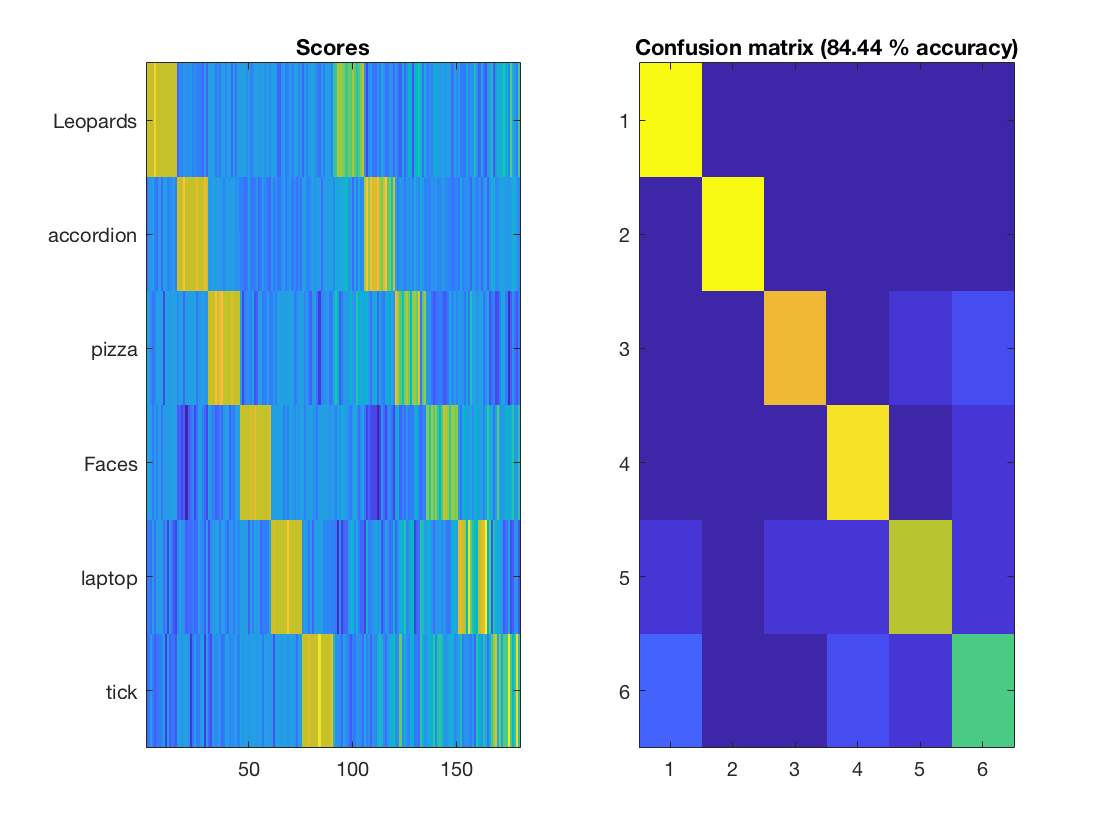

words = length(categorySubset);
modified_phow_caltech101(categorySubset, 'reduced-vocab', words);

A lower accuracy of 84.44% is observed.

modelPath = fullfile('data','reduced-vocab-model.mat'); load(modelPath); model;
vocabPath = fullfile('data','reduced-vocab-vocab.mat'); load(vocabPath); vocab

vocab = 128×6 single matrix
    1.1234   21.4543   11.6557   16.2007   19.2118   33.5356
    0.5161   14.6118   16.2311   17.1164   29.4251   11.7328
    0.7841   14.5942   37.5170   26.0759   16.7001    9.0970
    0.1945   16.7308   27.9172   12.9012   11.3330   22.3647
    0.3987   34.8277   16.1615   11.3468   20.2988   19.1328
    0.8197   14.9710   15.2203   13.3195   29.9366   10.4675
    0.6086    8.8258   28.0213   28.8944   16.2982   15.2576
    0.1987    9.2216   13.9126   16.7263   10.2820   39.3471
    0.2732   25.9330   14.8228   18.3160   31.5388   47.6233
    0.3282   16.4696   20.8563   22.4670   47.4100   16.9878


visualizeImgClass(imagePaths, model);

We observe that although the classification accuracy has gone down, in the sample studied, the majority of pizzas have been classified correctly. There are enough clusters to classify the categories quite well as they are equal in size. We now try with less words than categories. 

Training model for class tick
Training model for class laptop
Training model for class Faces
Training model for class pizza
Training model for class accordion
Training model for class Leopards


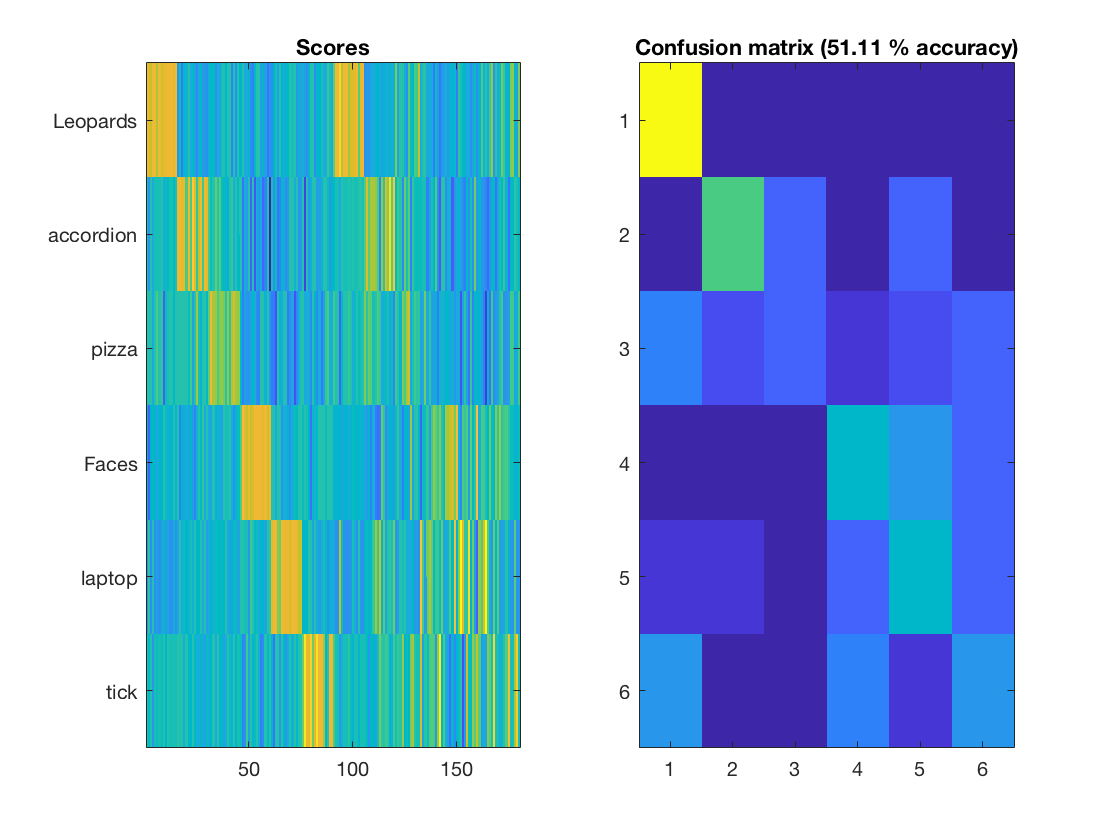

words = 2; modified_phow_caltech101(categorySubset, 'reduced-vocab', words);

We now observe a much lower classification accuracy (51.1%), as there are not enough words to classify each image to the different categories. Let's see whether the same images are classified.

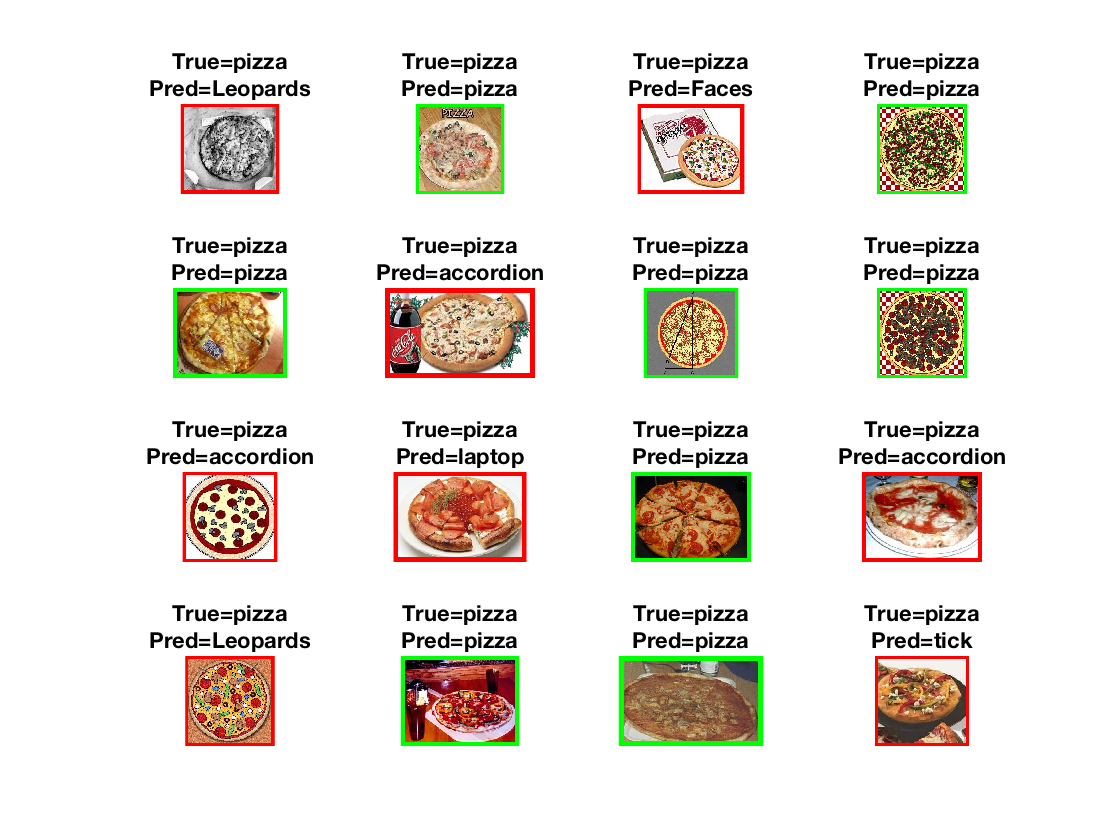

modelPath = fullfile('data','reduced-vocab-model.mat');
load(modelPath);
visualizeImgClass(imagePaths, model);

It is now observed that many of the same pizzas are now classified incorrectly. It important to have at least as many words as there are classification categories.

**d) **

**Explore and explain how the k-means is applied, which parameters are used, what is there meaning and what are the advantages and the limitations of the method.**

Code to construct vocabulary:

% vocab = vl_kmeans(descrs, conf.numWords, 'algorithm', 'elkan', 'MaxNumIterations', 50);

The image descriptors are passed to the kmeans algorithm as the data to cluster, and the number of words passed as an argument is used to determine the number of centroids that the kmeans algorithm will cluster the data to.

The algorithm chosen in the example is the 'elkan' algorithm, which is a fast version of the 'lloyd' algorithm, using triangular inequalities to optimize it. The 'lloyd' algorithm finds evenly spaced sets of points, which is what the k-means algorithm needs to find the centroid positions.

It finds a centroid for a set of points, and then re-partitions and re-calculates the centroids. The 'MaxNumIterations' parameter limits how many times it re-calculates in the case of it not converging before hand. Convergence is determined when the centroids are re-calculated but have not changed position since the last calculation. 

The advantages of k-means is that it is unsupervised, and therefore the labels of the data do not need to be known. Also the clusters produced by k-means can be reused on new data. So providing that the k-means algorithm has been clustered on a large amount of image categories and corresponding images, it can be used to cluster new data effectively.

However, selecting the ideal cluster size can sometimes be difficult, and once a cluster size has been determined, the whole algorithm has to be re-run to calculate a new cluster size.

**e) **

**The function getImageDescriptor gives the spatial histogram of the image. **

**What is the spatial histogram? **

It is a step of the object recognition by  Bag-of-Words algorithm done between the training visual words step and computing the feature kernel map. It consists of breaking the image down in cells and perform the histogram of visual words in each cell. Afterwards, the histograms of each cell are concatenated. This is done in order to keep spatial information which would have been lost if athe histogram is applied to the entire image only.

**What dimension does it have? **

The dimension of the histogram are the number of row cells times the number of columns cells (total number of partitions) times the number of visual words considered (bins). The "TinyProblem" settings of the code which considers only just 5 classes, have a 2 by 2 divisions (4 cells in total) with a total number of words value of 300. The size of the concatenated histogram sum up to 1200 values.  

**What happens if we augment model.numSpatialX from 2 to 4?**

First, the number of cells doubled together with the datapoints required in the histogram (2400). Secondly, the accuracy also increased from 92% to 96%. However, if model.numSpatialY is also set to 4, the number of histogram values increases to 4800 and the the average accuracy also improves up to 97.33%. Latest settings, all faces were correctly classified and the background images missclassified were reduced to 2.

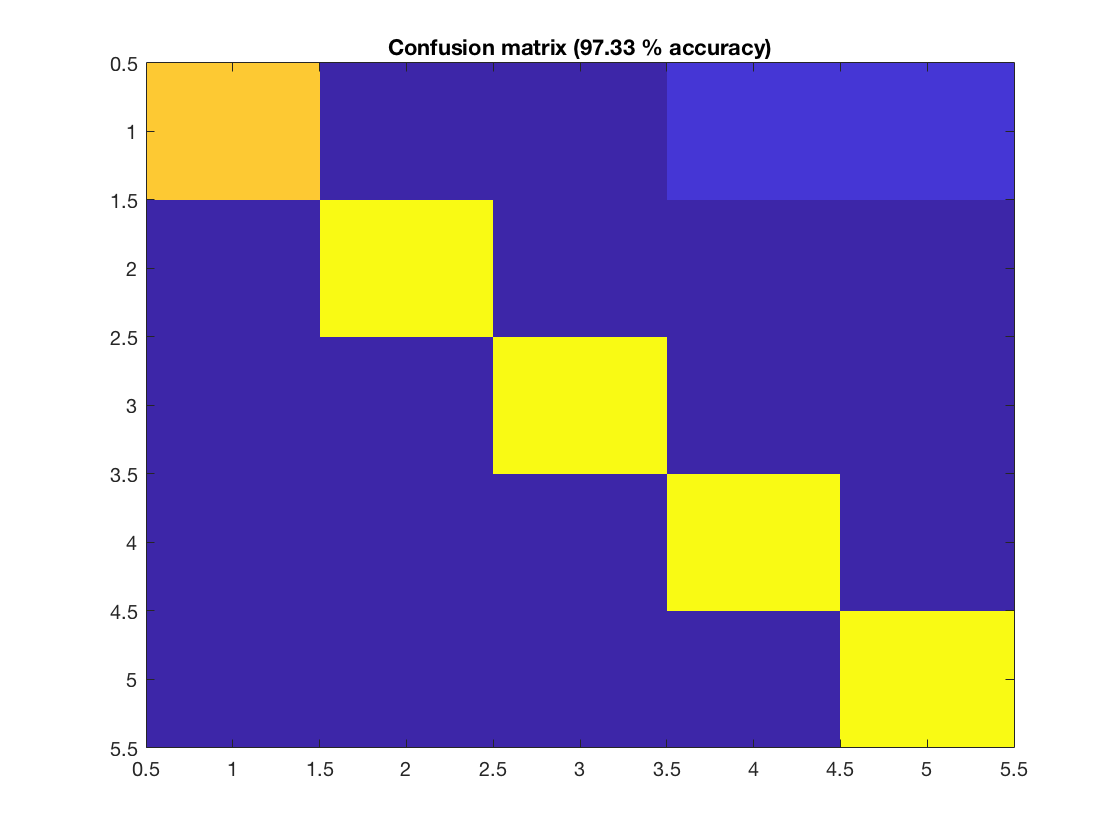

figure
imagesc([13 0 0 1 1; 0 15 0 0 0; 0 0 15 0 0; 0 0 0 15 0; 0 0 0 0 15]);
title(sprintf('Confusion matrix (%.2f %% accuracy)', 97.33)) ;

**f) **

**The SVM classification with homogeneous kernels is performed by the vl_svmtrain function that needs the homogeneous kernel map obtained by the vl_homkermap function. **

**What are the parameters obtained after the training process?**

The training process using SVM generates two main paramters named `W` (weights) and `b` (bias) which are persisted in the model object.

**What dimension do they have? **

A SVM model is trained for each class. 

The dimension of the weights of a single SVM model is the number of datapoints times the number of classes (1). With default settings of TinyProblem, the dimensions are 3600 x 1. The final W dimension of the training process will be the concatention of the weights for each class, with default settings, 5 classes (3600 x 5). The vector has a dimension of 3600 because the vl_homkermap computes a 2*N+1 dimensional approximated kernel map for the Chi2 kernel. The input vector of vl_homkermap is 1200 (the spatial histogram explained in e) and the value of N is 1. Thus 2*1+1 is 3, the output of the kernel map is 3 * 1200 = 3600 which is then passed to the SVM.

The dimension of the bias of a single SVM model is 1. Thus the final b dimension of the training process will be 1 x 5 (number of classes).

**How do you apply them to obtain the score of the final classification?**

The scores can be computed using the weights and the bias with the formula: $W^T X+b=Y$ and the sign of Y should match the Label or class vector made of -1 and +1 values.

**g)** 

**Is the algorithm invariant to rotation of the images? **

figure();

catName = 'Leopards';
mkdir(catName);

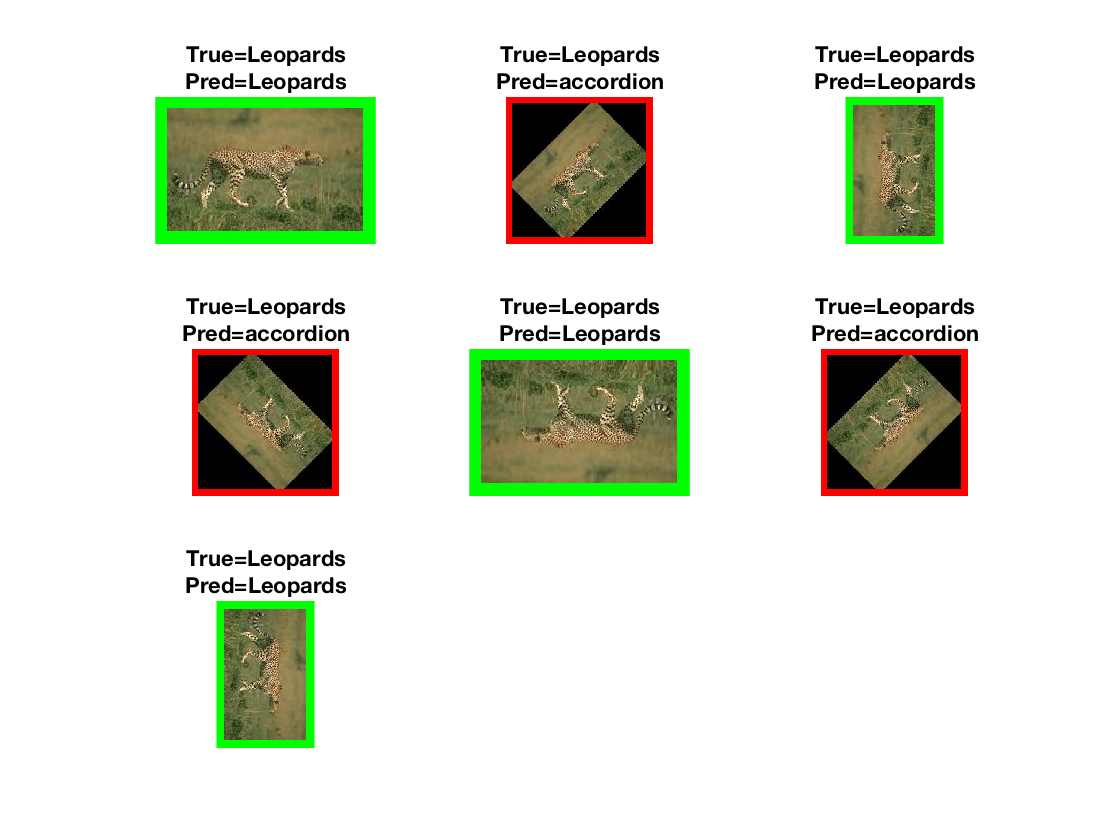

imgPath = fullfile('data','caltech-101','101_ObjectCategories',catName,'image_0001.jpg');
imgPaths = { imgPath };
imgData = imread(imgPath);
rotations = [45, 90, 135, 180, 225, 270];

for rotIdx=1:length(rotations)    
    rotation = rotations(rotIdx);
    name = strcat(catName, filesep, 'tmp_', num2str(rotation), '.jpg');
    imwrite(imrotate(imgData, rotation), name);
    imgPaths = horzcat(imgPaths, name);
end
modelPath = fullfile('data','baseline-model.mat');
load(modelPath);
visualizeImgClass(imgPaths, model);

It appears that the algorithm is invariant to rotations at multiples of only 90 degrees, however this is because the other rotations introduce black image borders which confuse the algorithm into believing it is an accordion.

figure();

catName = 'accordion';
mkdir(catName);

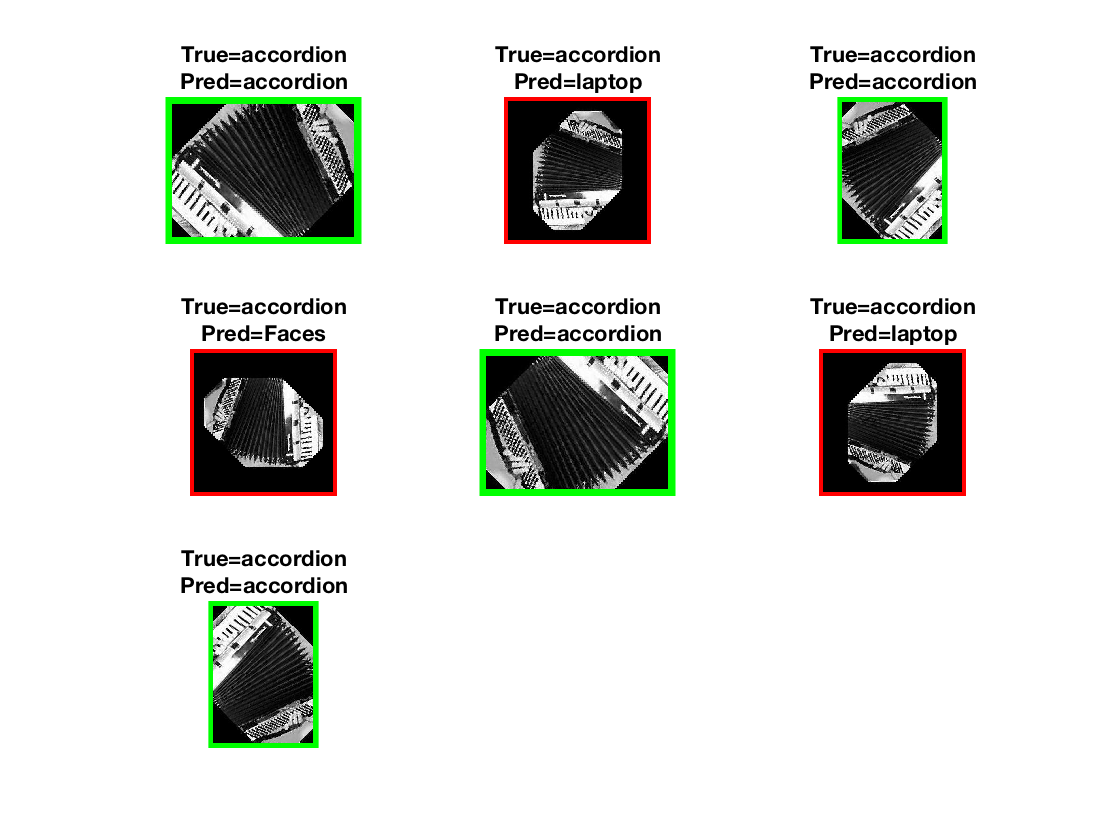

imgPath = fullfile('data','caltech-101','101_ObjectCategories',catName,'image_0007.jpg');
imgPaths = { imgPath };
imgData = imread(imgPath);
rotations = [45, 90, 135, 180, 225, 270];

for rotIdx=1:length(rotations)    
    rotation = rotations(rotIdx);
    name = strcat(catName, filesep, 'tmp_', num2str(rotation), '.jpg');
    imwrite(imrotate(imgData, rotation), name);
    imgPaths = horzcat(imgPaths, name);
end
modelPath = fullfile('data','baseline-model.mat');
load(modelPath);
visualizeImgClass(imgPaths, model);

With the accordion, we observe that the rotation confuses the algorithm, at rotations which are not a multiple of 90.

**Is the algorithm invariant to rescaling of the images?**

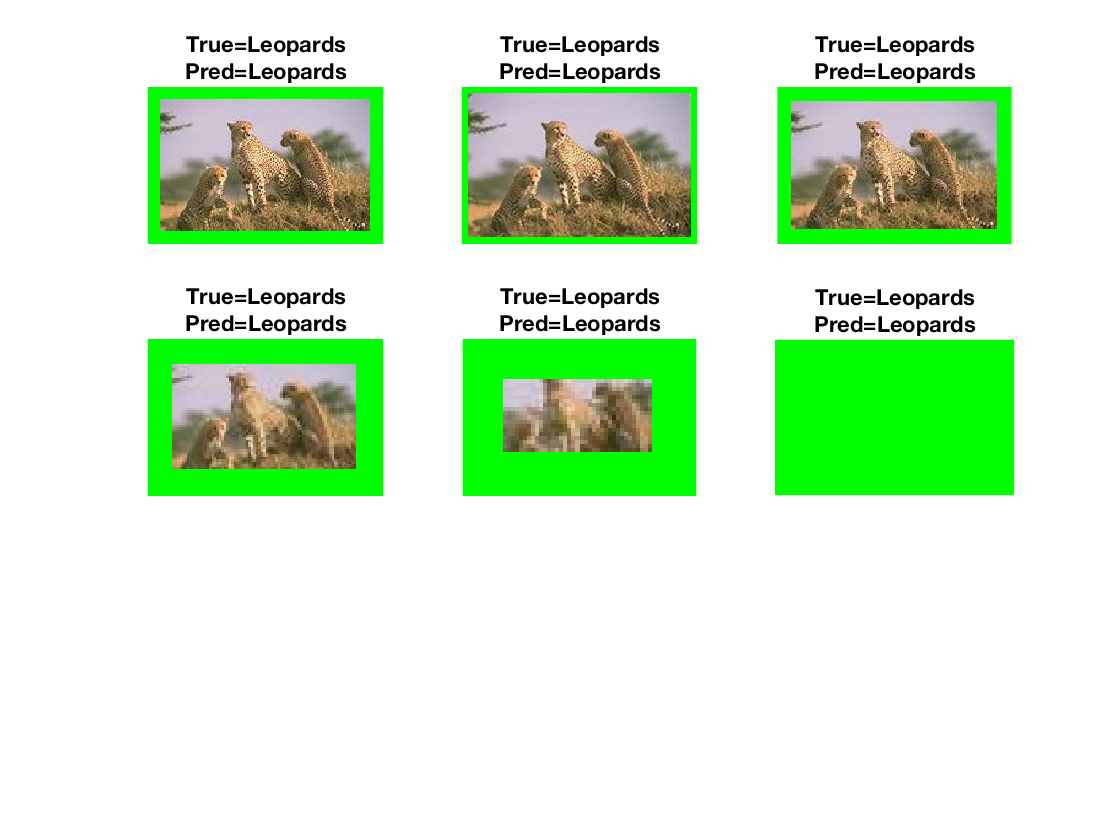

figure();

catName = 'Leopards';
imgPath = fullfile('data','caltech-101','101_ObjectCategories',catName,'image_0003.jpg');
imgPaths = { imgPath };
imgData = imread(imgPath);

scales = [2, 0.9, 0.5, 0.3, 0.1];
for scaleIdx=1:length(scales)    
    scale = scales(scaleIdx);
    name = strcat(catName, filesep, 'tmp_', num2str(scale), '.jpg');
    newImg = imresize(imgData, scale);
    imwrite(newImg, name);
    imgPaths = horzcat(imgPaths, name);
end

visualizeImgClass(imgPaths, model);

The algorithm is found to classify the leaopord at large and small scales.

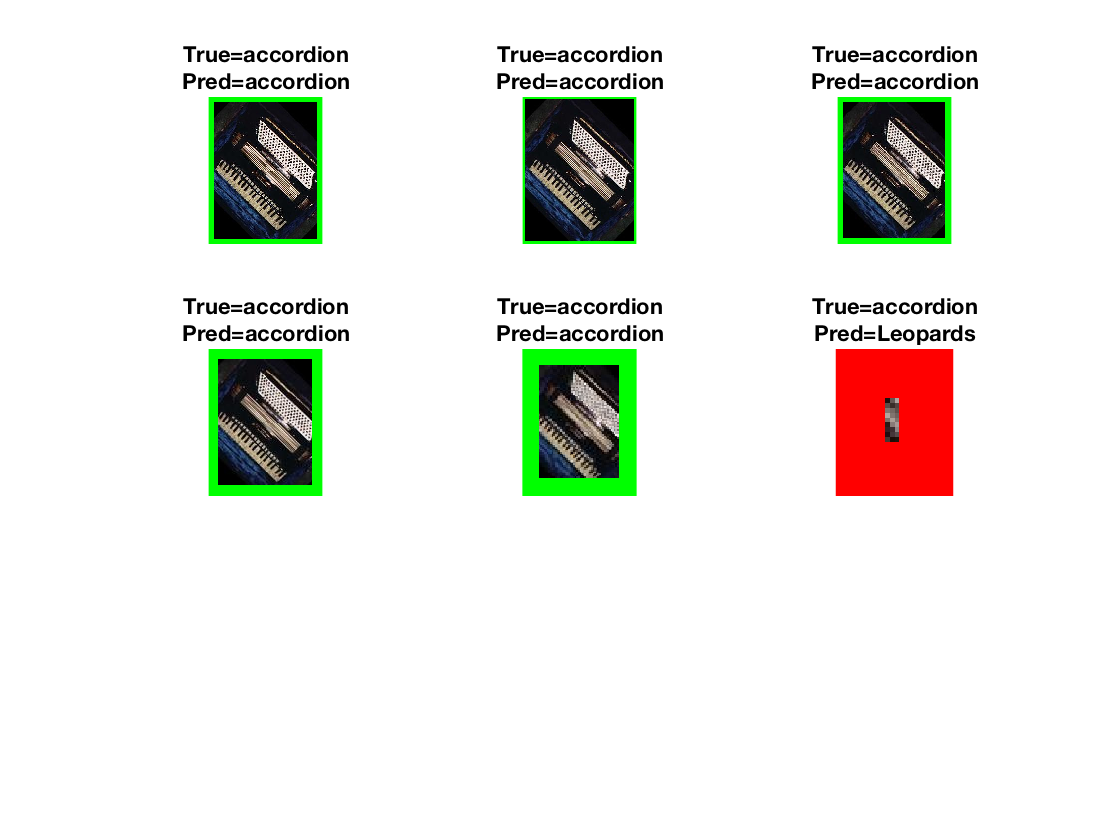

figure();

catName = 'accordion';
imgPath = fullfile('data','caltech-101','101_ObjectCategories',catName,'image_0002.jpg');
imgPaths = { imgPath };
imgData = imread(imgPath);

scales = [2, 0.9, 0.5, 0.3, 0.1];
for scaleIdx=1:length(scales)    
    scale = scales(scaleIdx);
    name = strcat(catName, filesep, 'tmp_', num2str(scale), '.jpg');
    newImg = imresize(imgData, scale);
    imwrite(newImg, name);
    imgPaths = horzcat(imgPaths, name);
end

visualizeImgClass(imgPaths, model);

However, it has trouble identifying the accordion at the smallest scale (0.1 of the original size).

**h)							**

**Compute how the F-score changes when the number of categories augment (e.g. from 5 to 10 to 15 to 100). **

**Setting 5 categories**

resultsPath = fullfile('data','baseline-result.mat');
load(resultsPath)
[F1, Precision, Recall] = f1Score(confus)

F1 =     1.0000    1.0000    0.9655    0.9333    0.9677    0.9333


Precision =     1.0000    1.0000    1.0000    0.9333    0.9375    0.9333


Recall =     1.0000    1.0000    0.9333    0.9333    1.0000    0.9333


mean(F1)

ans = 0.9667

**Setting 10 categories**

Training model for class wheelchair
Training model for class mandolin
Training model for class water_lilly
Training model for class crab
Training model for class tick
Training model for class laptop
Training model for class Faces
Training model for class pizza
Training model for class accordion
Training model for class Leopards


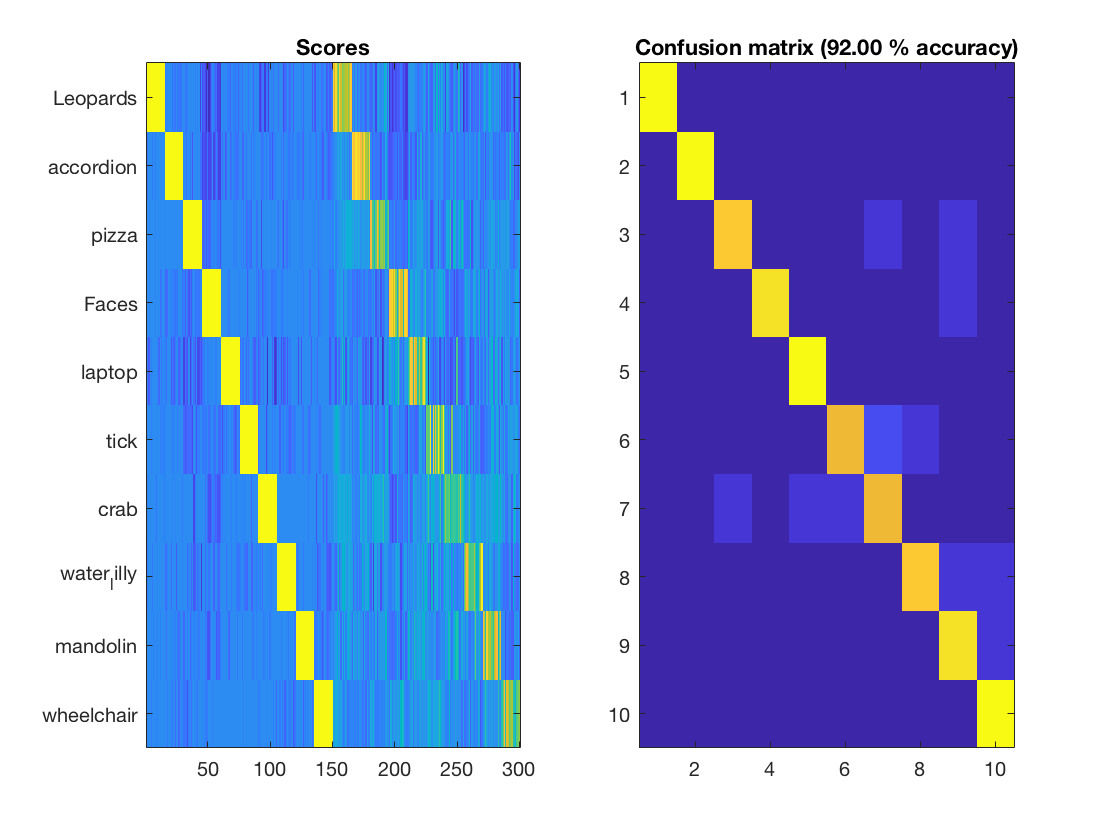

TenCategories = {'Leopards', 'accordion', 'pizza', 'Faces', 'laptop', 'tick',...
'crab', 'water_lilly', 'mandolin', 'wheelchair'};
			
modified_phow_caltech101(TenCategories, '10-categories');

resultsPath = fullfile('data','10-categories-result.mat');
load(resultsPath)
[F1, Precision, Recall] = f1Score(confus)

F1 =     1.0000    1.0000    0.8966    0.9655    0.9677    0.8571    0.8000    0.8966    0.8750    0.9375


Precision =     1.0000    1.0000    0.9286    1.0000    0.9375    0.9231    0.8000    0.9286    0.8235    0.8824


Recall =     1.0000    1.0000    0.8667    0.9333    1.0000    0.8000    0.8000    0.8667    0.9333    1.0000


mean(F1)

ans = 0.9196

**Setting 100 categories**

Training model for class wrench
Training model for class windsor_chair
Training model for class wild_cat
Training model for class wheelchair
Training model for class water_lilly
Training model for class watch
Training model for class umbrella
Training model for class trilobite
Training model for class tick
Training model for class sunflower
Training model for class strawberry
Training model for class stop_sign
Training model for class stegosaurus
Training model for class starfish
Training model for class stapler
Training model for class soccer_ball
Training model for class snoopy
Training model for class sea_horse
Training model for class scorpion
Training model for class scissors
Training model for class schooner
Training model for class saxophone
Training model for class rotated
Training model for class rooster
Training model for class rhino
Training model for class revolver
Training model for class pyramid
Training model for class platypus
Training model for class pizza
Training mod

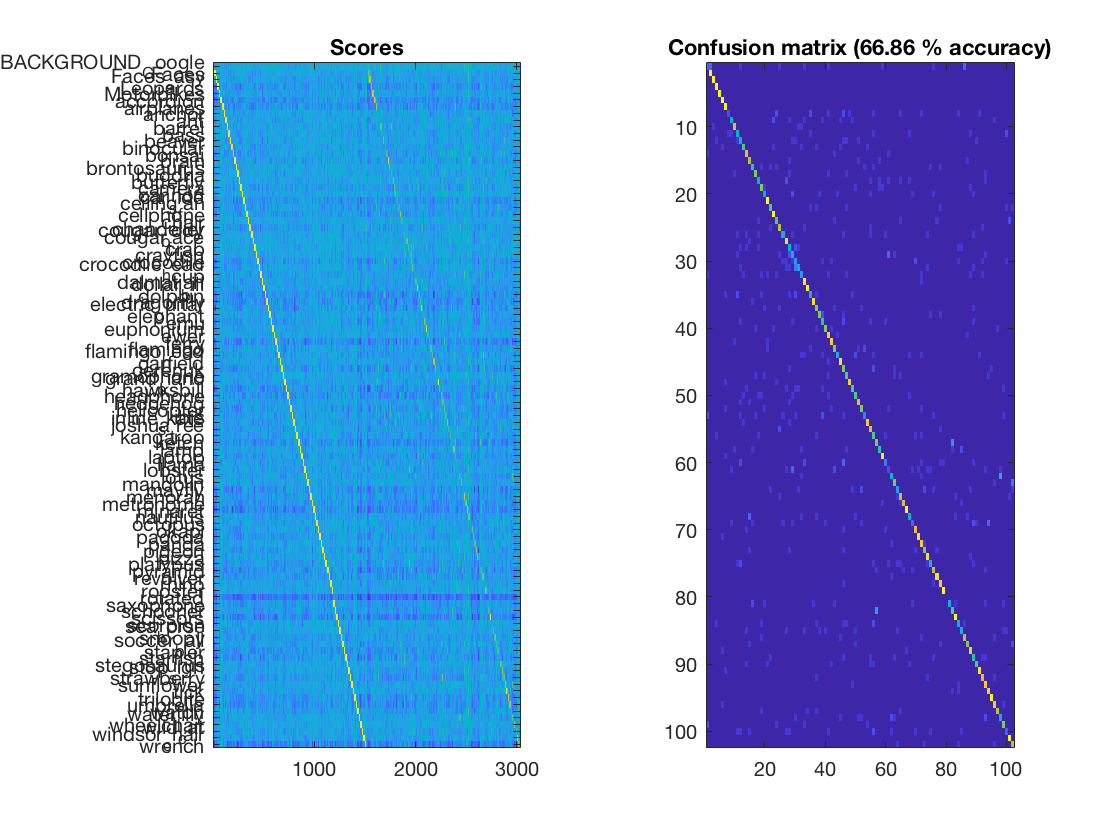

modified_phow_caltech101();

resultsPath = fullfile('data','baseline-result.mat');
load(resultsPath)
[F1, Precision, Recall] = f1Score(confus)

F1 =     0.2500    0.9091    0.9677    0.9091    1.0000    0.8824    0.8571    0.2222    0.5600    0.8000    0.4828    0.4242    0.6667    0.7273    0.6471    0.5714    0.7143    0.5185    0.6250    0.5185    0.8824    0.6429    0.8824    0.6000    0.6875    0.5000    0.7568    0.4118    0.3750    0.3125    0.4800    0.3846    0.7568    0.9677    0.4615    0.9333    0.5882    0.7407    0.5161    0.7407    0.7222    0.8125    0.6452    0.5217    0.8485    0.4878    0.6000    0.8966    0.6429    0.6000


Precision =     0.3333    0.8333    0.9375    0.8333    1.0000    0.7895    0.7500    0.6667    0.7000    0.8000    0.5000    0.3889    0.7500    0.6667    0.5789    0.6154    0.7692    0.5833    0.5882    0.5833    0.7895    0.6923    0.7895    0.6000    0.6471    0.6667    0.6364    0.3684    0.3529    0.2941    0.6000    0.4545    0.6364    0.9375    0.5455    0.9333    0.5263    0.8333    0.5000    0.8333    0.6190    0.7647    0.6250    0.7500    0.7778    0.3846    0.6000    0.9286    0.6923    0.6000


Recall =     0.2000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.1333    0.4667    0.8000    0.4667    0.4667    0.6000    0.8000    0.7333    0.5333    0.6667    0.4667    0.6667    0.4667    1.0000    0.6000    1.0000    0.6000    0.7333    0.4000    0.9333    0.4667    0.4000    0.3333    0.4000    0.3333    0.9333    1.0000    0.4000    0.9333    0.6667    0.6667    0.5333    0.6667    0.8667    0.8667    0.6667    0.4000    0.9333    0.6667    0.6000    0.8667    0.6000    0.6000


mean(F1)

ans = NaN

**i) Compute the F-score when different parameters of the algorithm are used.**

In this section, we are going to focus on how PHOW step and size parameters influence the mean F1 score. 

The number of words was fixed to a low value of 30 on purpose. It is known that low number of words tends to generalise too much and mix features together causing a low performance of the model. However, there may be a combination of step and size that could overcome the deficiency of using a low number of words. The categories used for the paramter optimization are: Background, Faces, Easy Faces, Leopards and Motorbikes, the default categories in the TinyProblem settings.

The sizes and steps values considered ranges from 3 to 12 in unit steps.  

Training model for class Motorbikes
Training model for class Leopards
Training model for class Faces_easy
Training model for class Faces
Training model for class BACKGROUND_Google
Training model for class Motorbikes
Training model for class Leopards
Training model for class Faces_easy
Training model for class Faces
Training model for class BACKGROUND_Google
Training model for class Motorbikes
Training model for class Leopards
Training model for class Faces_easy
Training model for class Faces
Training model for class BACKGROUND_Google
Training model for class Motorbikes
Training model for class Leopards
Training model for class Faces_easy
Training model for class Faces
Training model for class BACKGROUND_Google
Training model for class Motorbikes
Training model for class Leopards
Training model for class Faces_easy
Training model for class Faces
Training model for class BACKGROUND_Google
Training model for class Motorbikes
Training model for class Leopards
Training model for class Faces

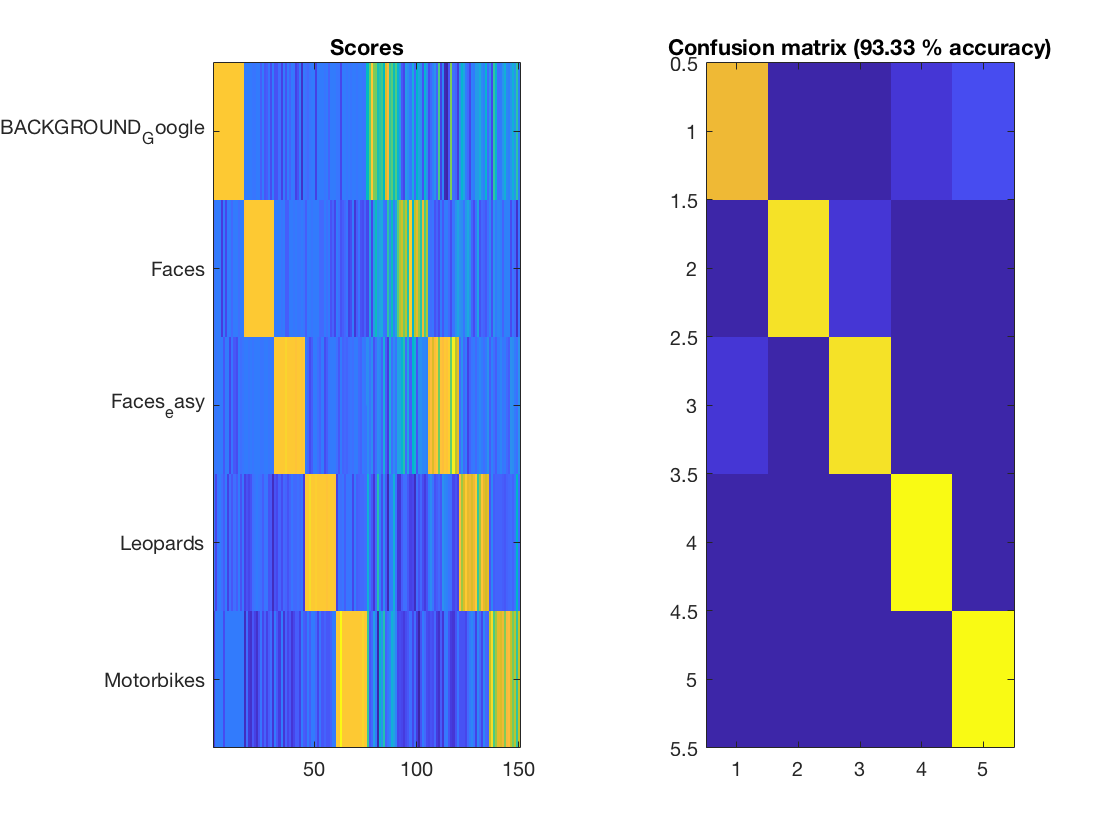

TinyCat = {'BACKGROUND_Google', 'Faces', 'Faces_easy', 'Leopards', 'Motorbikes'};

sizes = [3, 4, 5, 6, 7, 8, 9, 10, 11, 12];
steps = [3, 4, 5, 6, 7, 8, 9, 10, 11, 12];

[X,Y] = meshgrid(steps, sizes);
Z = zeros(size(X));
for i = 1:length(sizes)
    for j = 1:length(steps)
        opt = {'Sizes', sizes(i), 'Step', steps(j)};
        modified_phow_caltech101(TinyCat, 'f1-tests', 30, opt);
        load(fullfile('data','f1-tests-result.mat'));
        [F1, Precision, Recall] = f1Score(confus);
        Z(i,j) = mean(F1);
    end
end

Plotting the results:

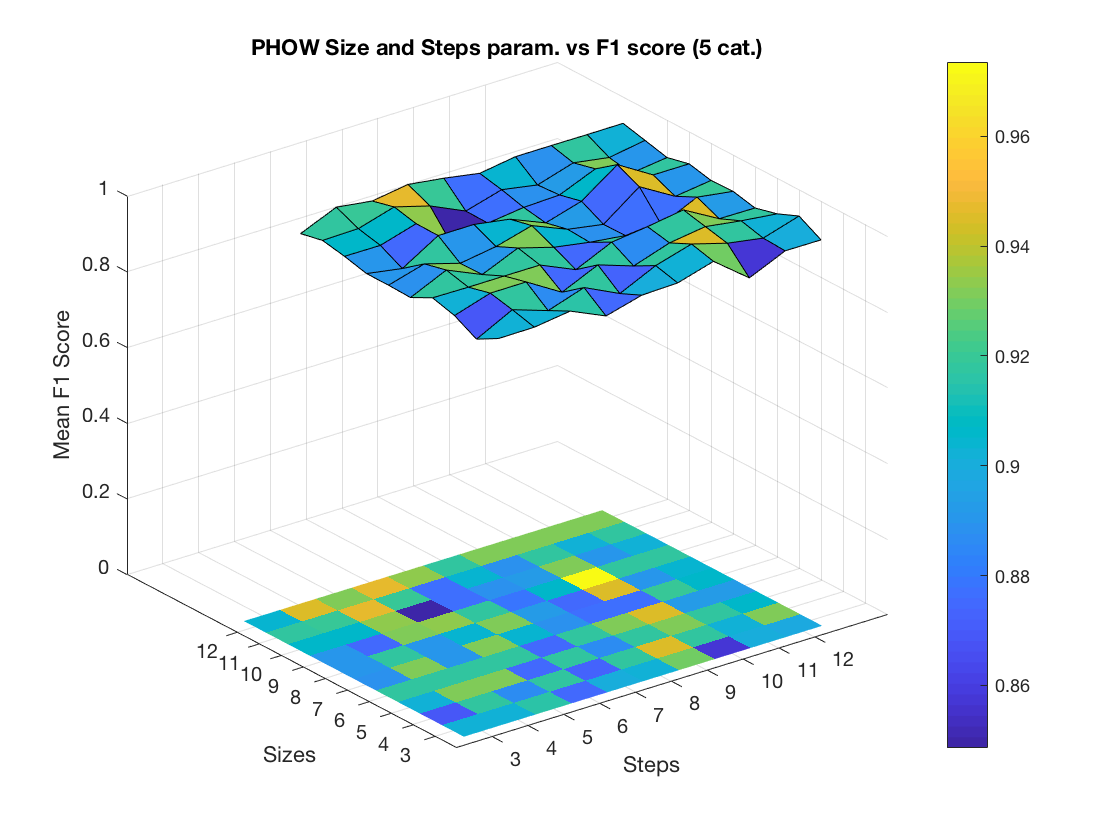

figure
surf(X,Y,Z), hold on, imagesc(Z), colorbar;
set(gca, 'ytick', 1:length(sizes), 'yticklabel', sizes); ylabel("Sizes");
set(gca, 'xtick', 1:length(steps), 'xticklabel', steps); xlabel("Steps");
zlabel("Mean F1 Score");
title("PHOW Size and Steps param. vs F1 score (5 cat.)");

The figure shows the surface of mean F1 score across 100 combinations of sizes and step values. The mean F1 scores goes from 0.85 to a maximum of 0.9733, the maximum is obtained with a size value of 9 and and step value of 10.  However, the surface seems a bit noisy and there is not a flat area of robust values. 